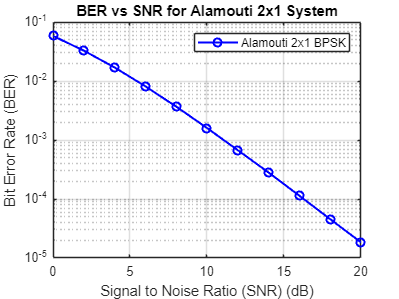



% Parameters
N = 1e4;                  % Number of bits to transmit per trial
snr_dB_values = 0:2:20;               % Range of snr values in dB
num_trials = 10000;       % Number of trials
ber_results = zeros(num_trials, length(snr_dB_values));  % Pre allocate array to store BERs
for i = 1:1:num_trials
    ber_results(i, :) = trial(snr_dB_values, N); % Run trial
end

ber_results_averaged = zeros(length(snr_dB_values));    % Pre allocate array to store average BERs

for i = 1:1:length(snr_dB_values)
    ber_results_averaged(i) = mean(ber_results(:, i));
end

% Plot BER vs snr
figure;
semilogy(snr_dB_values, ber_results_averaged, 'bo-', 'LineWidth', 1.5);
grid on;
xlabel('Signal to Noise Ratio (SNR) (dB)');
ylabel('Bit Error Rate (BER)');
title('BER vs SNR for Alamouti 2x1 System');
legend('Alamouti 2x1 BPSK');

function berResults = trial(snr_dB_values, N)
berResults = zeros(size(snr_dB_values));  % Pre-allocate BER array

% Generate random binary data
dataBits = randi([0, 1], N, 1);

% BPSK Modulation
bpskSymbols = 2*dataBits - 1;  % Map 0 -> -1, 1 -> +1

% Alamouti Encoding
s1 = bpskSymbols(1:2:end);  % Odd symbols
s2 = bpskSymbols(2:2:end);  % Even symbols
x1 = [s1, -conj(s2)];
x2 = [s2, conj(s1)];

% Define Rayleigh Channel for 2x1 System
h1 = (randn(size(s1)) + 1j*randn(size(s1))) / sqrt(2);  % Channel for Tx1 to Rx
h2 = (randn(size(s1)) + 1j*randn(size(s1))) / sqrt(2);  % Channel for Tx2 to Rx

% Transmit through channel
r1 = h1 .* x1(:, 1) + h2 .* x2(:, 1);  % Received signal at time t
r2 = h1 .* x1(:, 2) + h2 .* x2(:, 2);  % Received signal at time t+1

% Simulation loop over snr values
for i = 1:length(snr_dB_values)
    snr_db = snr_dB_values(i);
    snr_linear = 10^(snr_db / 10); % Convert snr from dB to linear
    noiseVar = 1 / (2 * snr_linear); % Noise variance for given snr
    
    % Add AWGN noise
    noise1 = sqrt(noiseVar) * (randn(size(r1)) + 1j*randn(size(r1)));
    noise2 = sqrt(noiseVar) * (randn(size(r2)) + 1j*randn(size(r2)));
    y1 = r1 + noise1;
    y2 = r2 + noise2;
    
    % Alamouti Decoding
    r_combined = conj(h1).*y1 + h2.*conj(y2);
    s_combined = conj(h2).*y1 - h1.*conj(y2);
    
    % Hard Decision Detection
    receivedSymbols = zeros(2*length(s1), 1);
    receivedSymbols(1:2:end) = real(r_combined) > 0;  % Detection for s1
    receivedSymbols(2:2:end) = real(s_combined) > 0;  % Detection for s2
    
    % Calculate Bit Errors
    numErrors = sum(receivedSymbols ~= dataBits);
    berResults(i) = numErrors / N;
end
end